# K-Nearest Neighbours Classification

In this lab sheet we'll look at how to train and use a K-Nearest Neighbours (k-NN) classifier using built-in Matlab functions. Prerequisites:

- **You need to: (i) download a copy of the iris.csv dataset from Moodle; (ii) store it in the same directory as this live script; and (iii) set Matlab's Current Folder to point at that directory**;

- This script assumes you have completed the Matlab Fundamentals materials.

## Loading up a dataset

To experiment with k-NN classification, we need some data to work with. We're going to use the "iris" dataset. The iris dataset contains information about the sizes of different species of iris. It's a really good dataset to work with while getting started with machine learning because it's simple and easy to understand, and it's relatively small. It's available on Moodle as a download (you just need to save it to the same directory you're running this script from) so let's load it up as a table and have a look:

data = readtable('iris.csv');

The table holds measurements of the petal and sepal widths/lengths (see image below) for 150 irises. In the final column is the species the iris belongs to (Setosa, Versicolor, or Virginica), and the challenge is to accurately predict which species any iris belongs to just from its sepal/petal measurements.

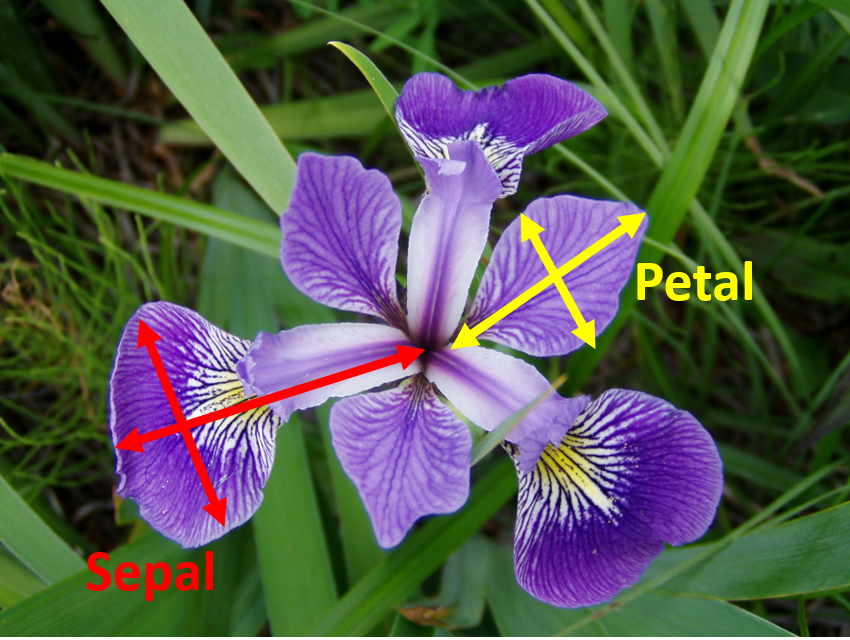

Let's see a summary of the data in our table:

summary(data);


Variables:

    sepal_length: 150×1 double

        Values:

            Min            4.3      
            Median         5.8      
            Max            7.9      

    sepal_width: 150×1 double

        Values:

            Min              2     
            Median           3     
            Max            4.4     

    petal_length: 150×1 double

        Values:

            Min               1     
            Median         4.35     
            Max             6.9     

    petal_width: 150×1 double

        Values:

            Min            0.1     
            Median         1.3     
            Max            2.5     

    species: 150×1 cell array of character vectors



The "species" column contains the feature which we want to be able to predict. Data from this column is stored in a cell array of text values which are either "setosa", "versicolor", or "virginica", and there are 50 of each. Let's have a look:

data{1:1:end, 'species'}

ans = 150×1 cell array
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'versicolor'}
    {'ve

Because the feature can only take three possible values, it's a categorical feature. And because we're trying to predict a categorical feature, we have a *classification problem*. The k-NN classifier is a suitable predictive model to solve our classification problem with.

The other columns in the table contain the features which we want to use to try and predict the species. These columns all contain numeric data, and are stored in arrays of double precision numbers. Let's have a look at the first 25 values of "sepal_length" as an example: 

data{1:1:25, 'sepal_length'}

ans =     5.1000
    4.9000
    4.7000
    4.6000
    5.0000
    5.4000
    4.6000
    5.0000
    4.4000
    4.9000


I guess these measurements are in cm, but I don't know for sure, and that's OK. Our only job is to see if we can establish a reliable connection between these features and the different species, using machine learning.

## Visualising the dataset

If we plot the sepal measurements we can get a sense of why this classification problem might be challenging.

To plot the data we'll use Matlab's `gscatter()` function. The function is a lot like the `scatter()` function we met in the Matlab fundamentals materials, but it's specifically for plotting groups of data ("gscatter" is short for "grouped scatter"). First, let's see it in action, and then we'll describe how it's working:

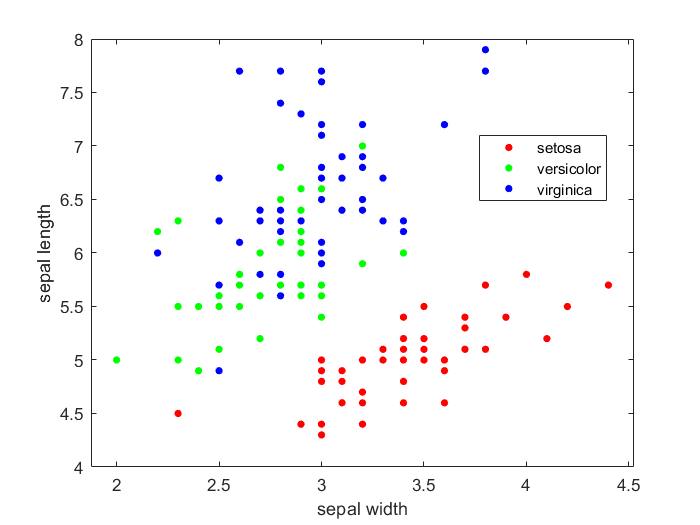

% call gscatter() to visualise all the data in one go:
gscatter(data{:,'sepal_width'}, data{:,'sepal_length'}, data{:,'species'});
xlabel('sepal width');
ylabel('sepal length');

The first two arguments are the same as they are for the `scatter()` function: the x-coordinates of the points you want to display, followed by the y-coordinates of the points you want to display. The extra third argument is an array specifying which group each point belongs to. Matlab will use this array to automatically colour code the points and then display a legend for us.

Now we have a method for visualising the data, let's think about the what the visualisation tells us.

The "setosa" class (red) tends to have wider, shorter sepals, and is nicely separated from the other species. However, the "versicolor" and "virginica" classes have quite similar distributions of sepal sizes and this makes them challenging to classify correctly regardless of what classifier we use.

Next let's have a look at the petal measurements:

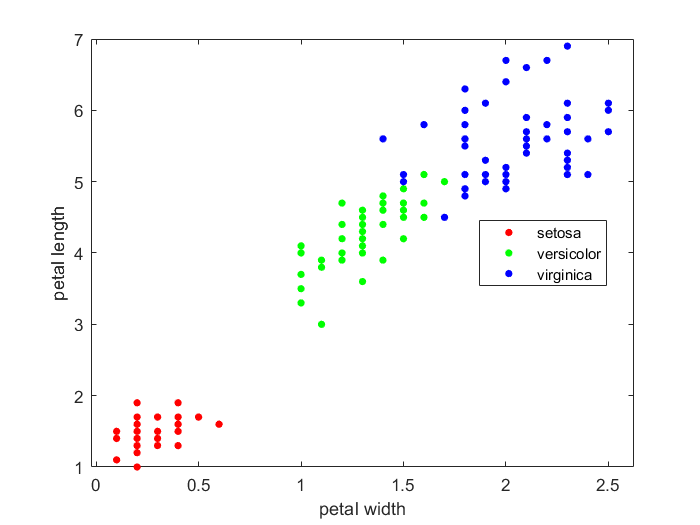

% call gscatter() to visualise all the data in one go:
gscatter(data{:,'petal_width'}, data{:,'petal_length'}, data{:,'species'});
xlabel('petal width');
ylabel('petal length');

The "setosa" class is quite well separated from the other species again (with short, thin petals), and should hopefully be quite easy to classify. The separation of the "versicolor" and "virginica" classes is also better in terms of their petal measurements. There is still some small overlap between the two, but hopefully by considering petal measurements *and *sepal measurements together at the same time, we can perform classification quite reliably.

## Separating training and testing data

We'll start by splitting up our dataset into two different pieces: one for training our classifier, and one for testing our classifier. This is the "horizontal split" we mentioned in lectures and taking this approach helps us to avoid *overfitting* our data.

A standard approach is to set aside approximately 25% of your data for testing, and use only the remaining 75% for training. Let's do a calculation to find how many examples we'd need to hold out:

nTest = round(0.25 * size(data,1))

nTest = 38


% things to try in the command window if you're not sure how this command is working:
% what do the following commands return:
% size(data)
% size(data,2)
% size(data,1)
% How about the following commands:
% round(10.9)
% round(10.1)
% round(10.5)

So we'd want to hold out 38 of our examples (the rows in our table) in order to test our classifier. We'll call this our *testing data*.

And this would leave us with 150 - 38 = 112 examples to train our classifier with. We'll call this our *training data*.

We want both the training data and the testing data to be representative of the original dataset. Remember that this had an equal number of examples of each species (50 of each). If the examples in our dataset were ordered at random, then it would be safe for us to take the first 38 for our testing dataset, and the next 112 for our training dataset:

data_test = data(1:1:nTest, :);
size(data_test)

ans =     38     5


data_train = data(nTest+1:1:end, :);
size(data_train)

ans =    112     5


We have to be careful though, because datasets are often sorted in some way before being exported. Remember when we displayed the "species" column further up, that the iris dataset is sorted by species name (50 setosas followed by 50 versicolors, followed by 50 virginicas). If we just split the dataset as we do in the code above, then we would end up with very unrepresentative data in both of our new datasets (e.g., the test data would *only* contain irises from the "setosa" class). For this reason, it's best to randomly re-order, or "shuffle", the rows in our dataset before we divide it up to make up our new testing and training datasets.

The function `randperm()` can help us do this shuffling. Calling `randperm(n)` returns an array containing a randomly reordered set of the integers from `1` to `n` inclusive, for example:

randperm(5)

ans =      1     2     5     4     3


randperm(5)

ans =      3     4     2     5     1


randperm(5)

ans =      3     5     1     4     2


Using `randperm()`, we can shuffle our dataset, and then safely divide it up into two new datasets in just the same way as we did above:

% shuffle the data and create a testing dataset and a training dataset:
data_shuffled = data(randperm(size(data,1)), :);
data_test = data_shuffled(1:1:nTest, :);
size(data_test)

ans =     38     5


data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =    112     5


The `randperm()` function will produce randomly reordered sets of integers every time you call it. While we're still finding our way with machine learning, it can be quite useful to have the same random set generated each time. This way you'll get the same results every time you run the code, and the same results as anyone else who runs the code. This can be done by re-seeding Matlab's random number generator:

% re-seed Matlab's random number generator
%rng(1)

Now we can repeat the steps from above and we're guaranteed the same results every time we run this live script:

% shuffle the data and create a testing dataset and a training dataset:
data_shuffled = data(randperm(size(data,1)), :);
data_test = data_shuffled(1:1:nTest, :);
size(data_test)

ans =     38     5


data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =    112     5


Let's have a look at the first few lines of each table:

data_test(1:1:5,:)

ans = 5×5 table
    sepal_length    sepal_width    petal_length    petal_width      species   
    ____________    ___________    ____________    ___________    ____________

        5.4             3.9            1.7             0.4        'setosa'    
        5.4             3.7            1.5             0.2        'setosa'    
        6.8             2.8            4.8             1.4        'versicolor'
        5.4             3.4            1.5             0.4        'setosa'    
        6.9             3.1            5.1             2.3        'virginica' 


data_train(1:1:5,:)

ans = 5×5 table
    sepal_length    sepal_width    petal_length    petal_width      species   
    ____________    ___________    ____________    ___________    ____________

        5.8             2.7            5.1             1.9        'virginica' 
        5.2             3.4            1.4             0.2        'setosa'    
          6             2.2              4               1        'versicolor'
        6.4             3.2            5.3             2.3        'virginica' 
        5.3             3.7            1.5             0.2        'setosa'    


## Separating class labels

Next, we want to separate the feature we're trying to predict into its own array. This is the "vertical split" we mentioned in lectures, and it helps us to keep the distinction between the features we *predict from* and the feature we're trying *to predict* clear in our minds. However, it's also necessary in practical terms: we have to pass these two things as separate arguments to the Matlab function that trains our classifier, and similarly, we need to separate out the true values of the feature we're trying to predict when we come to evaluate the classifier's performance on the testing data.

The "species" column contains the feature values that we're trying to predict. Because it contains categorical data it's worth us converting it to a categorical variable as we copy it (this will allow us to do things later on that we couldn't do if we left it as a cell array, e.g., view summaries of the contents, and pass it to built-in functions like `mode()` to find measures like the most common value). The code below separates out the species column from both the training data and testing data. As in lectures, we refer to the collection of features we use to *predict from* as an "example" and the associated feature we're trying *to predict* as its "class label", or just "label" for short:

% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test{:,'species'});
test_examples = data_test;
test_examples(:,'species') = [];
% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:,'species'});
train_examples = data_train;
train_examples(:,'species') = [];

## Training a k-NN classifier

Now we have our data organised, we can train a k-NN classifier using k=10 nearest neighbours by calling Matlab's `fitcknn()` function.

The input arguments to `fitcknn()` are:

- `train_examples` - our table of training examples

- `train_labels` - our categorical array of associated class labels

- A name-value pair argument which sets the number of neighbours that will be considered when classifying a new example, to 10

- A name-value pair argument which says whether we want to perform z-score standardization on our data (true - yes, false - no)

The output from the `fitcknn()` function is:

- `m` - an object containing our trained model

After you run the following command, the properties of the resulting object, `m`, will be printed out. You will hopefully recognise at least some of them (e.g., the 'Distance' measure being used):

% train a k-NN classifier from the training data:
m = fitcknn(train_examples, train_labels, 'NumNeighbors', 10, 'Standardize', true)

m =   ClassificationKNN
           PredictorNames: {'sepal_length'  'sepal_width'  'petal_length'  'petal_width'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 112
                 Distance: 'euclidean'
             NumNeighbors: 10


  Properties, Methods


## Use your trained classifier for prediction

Once you have trained your model, you can use it to classify new examples where you **don't** already know the value of the associated class label.

We'll try to classify the examples in our testing data. In truth, we know the true class labels for these examples, but we won't pass them to the classifier, and we'll use them later on to measure how accurate the classifier's predictions were.

To predict class labels for our testing examples based only on the features they contain we call Matlab's `predict()` function.

The input arguments to `predict()` are:

- `m` - the trained model we want to use to make the predictions

- `test_examples` - our table of testing examples

The output from `predict()` is:

- `predictions` - an array of predicted class labels; one for each example (row) in the table `test_examples`

% use our trained k-NN classifier to classify the testing data:
predictions = predict(m, test_examples);

Let's have a look at the first 25 predictions:

predictions(1:25)

ans = 25×1 categorical array
     setosa 
     setosa 
     versicolor 
     setosa 
     virginica 
     virginica 
     versicolor 
     virginica 
     virginica 
     setosa 
     setosa 
     virginica 
     versicolor 
     setosa 
     setosa 
     virginica 
     virginica 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     setosa 
     versicolor 
     setosa 
     virginica 


## Evaluating a classifier's performance

We could look through the list of predictions and compare them one-by-one against the original species values in `test_labels`. Or we could even use Matlab to plot the two columns out and compare them visually. But what we'd really like is a fast and compact way to measure the classifier's performance. A *confusion matrix* offers exactly that. A confusion matrix compares the true class labels against the predicted class labels and summarises the agreements and disagreements quantitatively.

First let's build a confusion matrix for the predictions we just generated, and then we'll look at what the matrix shows.

A confusion matrix is built with a call to the `confusionmat()` function.

The input arguments to `confusionmat()` are:

- `labels` - the true values of the class labels

- `predictions` - the values of the class labels predicted by our model

The outputs from `confusionmat()` are:

- `c` - a square array containing the confusion matrix itself

- `order` - a categorical array holding the labels for the rows/columns of the confusion matrix

% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =     12     0     0
     0    11     2
     0     2    11


order = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


Make sure you've run (up to and including) the above line and seen its output before reading further.

The confusion matrix is computed by comparing the true values of the class label with the values predicted by the classifier one-by-one. Each row of the confusion matrix tells us about the performance of the classifier for a particular value of the true class label. A record of which row tells us about which class is stored inside the array `order` (first entry relates to the first row, second entry to the second row, etc). In our case, the first row tells us about performance whenever the true class associated with an example was "setosa". Reading across the columns for the first row, the confusion matrix then shows us the number of occasions when an example which truly belonged to the class "setosa" was classified as belonging to each of the three possible classes. Again, the `order` array stores the record of which column relates to which class (first entry relates to the first column, second entry to the second column, etc). In our case the possible class labels are  "setosa", "versicolor", or "virginica", but confusion matrices work in just the same way no matter how many different classes you're dealing with. Reading across the first row of our confusion matrix we see that for all the examples that truly were of class "setosa" 12 were correctly assigned to the class "setosa", 0 were incorrectly assigned to the class "versicolor",  and 0 were incorrectly assigned to the class "virginica". As we suspected from our plots above, the setosa class is reasonably easy to classify.

Similarly, reading across the columns for the second row, we see that for all the examples that truly were of class "versicolor", 0 were incorrectly assigned to the class "setosa", 10 were correctly assigned to the class "versicolor", and 0 were incorrectly assigned to the class "virginica". 

Finally, reading across the columns for the third row, we see that for all the examples that truly were of class "virginica", 0 were incorrectly assigned to the class "setosa", 4 were incorrectly assigned to the class "versicolor", and 12 were correctly assigned to the class "virginica". Again, as we suspected from our plots above, the "versicolor" and "virginica" species are harder to tell apart.

What we hope for when looking at a confusion matrix is to see a "strong diagonal", that is - big numbers along the diagonal line running from the top left of the matrix to the bottom right (representing correctly classified examples), and small numbers away from that diagonal line (representing incorrectly classified examples).

The following numbers are of interest:

- The total of the numbers on a given row tell us how many examples really were in that class (so for our data: 12 setosas 10 versicolors and 16 virginicas)

- The total of the numbers along the diagonal line running from the top left of the matrix to the bottom right tell us how many examples were correctly classified (so for our data: 34)

- The total of all the numbers in the confusion matrix gives the total number of examples that the classifier attempted to classify (so for our data: 38)

Dividing measure 2 by measure 3 gives the proportion of all the classifications made by the classifier which were correct. This single number is a simple measure of classifier performance, and you can calculate it as follows:

% calculate the overall classification accuracy:
p = sum(diag(c)) / sum(c(1:1:end))

p = 0.8947


% things to try in the command window if you're not sure how this command is working:
% What do the following commands return:
% c
% c(1:1:end)
% sum([1 2 3])
% sum([1 2 3 4])
% sum([1 2 3 4 25])
% diag(c)

Or as a percentage, the classifier was correct 89.5% of the time (to one decimal place).

## Tasks

Try training and testing a k-NN classifier using the "wisc_bc_data.csv" dataset you used in the Matlab fundamentals materials and k=15. You'll need to work through the following steps and you can copy and paste code from the sections above to help you with each one:

- Load up the dataset

- Shuffle the dataset and separate it into training data and testing data

- Separate out the class labels in both your training data and testing data

- Train the classifier with your training data

- Test the classifier on your testing data

- Evaluate the classifier's performance by computing a confusion matrix

- Compute the overall proportion of correct classifications

% write your code on the lines below
% (it's expected that much of it will come from copying, pasting
% and editing code from further up in this live script)
data = readtable('wisc_bc_data.csv')

data = 569×32 table
        id         diagnosis     radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavit

% need to ignore id and then check diagnosis to all other columns
data(:,'id') = []

data = 569×31 table
     diagnosis     radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    con


nTest = round(0.25 * size(data,1))

nTest = 142

% rng seed
% rng(1)
data_shuffled = data(randperm(size(data,1)), :);
data_test = data_shuffled(1:1:nTest, :);
% could remove ID here and create copy so that order is the same and you are
% able to recover ID if needed
size(data_test)

ans =    142    31


data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =    427    31


% data loaded, shuffeled and seperated

% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test{:,'diagnosis'})

test_labels = 142×1 categorical array
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benig

test_examples = data_test;
test_examples(:,'diagnosis') = [];
% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:,'diagnosis'});
train_examples = data_train;
train_examples(:,'diagnosis') = [];

% train a k-NN classifier from the training data: ---
% NumNeighbors is kNN 15
m = fitcknn(train_examples, train_labels, 'NumNeighbors', 15, 'Standardize', true)

m =   ClassificationKNN
           PredictorNames: {1×30 cell}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 427
                 Distance: 'euclidean'
             NumNeighbors: 15


  Properties, Methods



% test 
predictions = predict(m, test_examples);
predictions(1:25)

ans = 25×1 categorical array
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 



% Evaluation
[c,order] = confusionmat(test_labels, predictions)

c =     85     1
     4    52


order = 2×1 categorical array
     Benign 
     Malignant 


knn_p = sum(diag(c)) / sum(c(1:1:end))

knn_p = 0.9648

save('save_data.mat', 'knn_p','-append')

